Veterans it is!


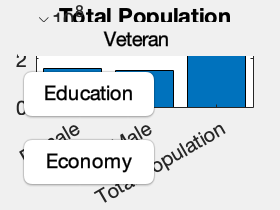

options = 1×3 string array
    "Total Population"    "Male"    "Female"


Total Population is 309349689
Male is 152089450
Female is 157260239




pick = menu('Title','Age & Sex','Education','Economy');
 
switch(pick)
case 1
       %If the user picks ceil, the thing on case 1 will be the output, in this
%case disp(ceil(x))
    fprintf('Veterans it is!\n')
    Agesex = menu('Title','Population', 'Age','Race');
    switch(Agesex)
        case 1
            whatyear= menu('Pick A Year','2010','2011','2012','2013','2014','2015','2016','2017','2018','2019','2010-2019');
            switch(whatyear)
                
                case 1
                    year2010 = table2struct(readtable('2010Age & Sex.xlsx', 'PreserveVariableNames', true));
                 year2010pickacategory=   menu('Pick a category','Total Population','Age','Race');
                 switch(year2010pickacategory)
                     case 1
                         totalpopulationplace=[];
                         a= length(year2010);
                         for i =1: a
                             if isequal(year2010(i).Label,'Total population')
                                 %totalpopulationplace= [totalpopulationplace i];
                                 z=1;
                             end
                         end
                       %  totalpopulationplace = [totalpopulationplace, 4, 5];
                       totalpopulationplace = [2, 3, 4];
                         first3datafortotalpopulation = [];
                        
                         for i=1: length(totalpopulationplace)
                              
                             gettingelement = totalpopulationplace(i);
                        
                            numberr= year2010(gettingelement).Estimate;
                            numberr = erase(numberr,',');
                            numberr = str2num(numberr);
                             first3datafortotalpopulation = [first3datafortotalpopulation numberr];
                             
                                 
                         end
       
                      x = categorical({'Total Population','Male','Female'});
                         bar(x,first3datafortotalpopulation);
                         title('Total Population');
                         
                         options= ["Total Population", "Male","Female"];
                         for i = 1:length(first3datafortotalpopulation)
                             fprintf('%s is %d\n',options(i), first3datafortotalpopulation(i))
                         end
                     case 2
                     case 3
                      
       
                 end
                case 2
                case 3
                
                
                
                
                
                
                
                
            end
        case 2 
            fprintf('Veteran 2\n')
    end
 
case 2

    fprintf('Education')
    Educationn = menu('Education1, Education2')
    switch(Educationn)
       case 1
            fprintf('Education 1\n')
        case 2 
            fprintf('Education 2\n')
    end
case 3 
%If the user picks sign, the thing on case 3 will be the output, in this
%case disp(sign(x))
 
      fprintf('Economy')
      Economyy = menu('Economy 1', 'Education 2')
      switch(Economyy)
           case 1
            fprintf('Economy 1\n')
        case 2 
            fprintf('Economy 2\n')
      end
    
    
end